clear variables; close all;clc
% extended kalman filter example 1
% tracking of an airplane
% states = (distance, velocity, altitude) = (x, xdot, y)
% measures = (range, bearing) = (slant, elevation angle) = (r, etha)

addpath('../utilities');

% time step [s]
dt = 0.05;

% 20 seconds of measures
endtime = 20;

% number of measures
n = endtime/dt+1;

% std of the two sensors
slant_range_std = 5;

% aircraft information
ac_pos = [0, 1000];
ac_vel = [100, 0];
ac_vel_std = 0.02;

% radar information
r_pos = [0, 0];

% dimensions
dim_x = 3;
dim_z = 1;

% initial condition
% mean
x = [ac_pos(1) - 100, ac_vel(1) + 100, ac_pos(2) + 1000]';
% covariance
P = diag([50^2, 50^2, 50^2]);

% process noise covariance
Q(1:2,1:2) = [0.25*dt^4 0.5*dt^3; 0.5*dt^3 dt^2]*0.1;
Q(3,3) = 0.1;

% measure noise covariance
R = diag(slant_range_std^2);
  
% (non linear) state transition function
f = @(x, dt) f_radar(x, dt);

% (non linear) measurement function
h = @(x) h_range(x);
  
% linearized state transition function
F = [1, dt, 0;0, 1, 0;0, 0, 1];
    
% data structures
x_posterior = zeros(dim_x, n);
zs = zeros(dim_z, n);
xs = zeros(dim_x, n);
P_posterior = cell(1, n);
x_posterior_mat = zeros(dim_x, n);
P_posterior_mat = cell(1, n);

% matlab filter
ekf = extendedKalmanFilter(@(x) f_radar(x, dt), @(x) h_range(x), x);
ekf.State = x;
ekf.StateCovariance = P;
ekf.StateTransitionFcn = @f_radar;
ekf.StateTransitionJacobianFcn = @(x, dt) F;
ekf.ProcessNoise = Q;
ekf.MeasurementFcn = @h_range;
ekf.MeasurementJacobianFcn = @h_radar_jacob;
ekf.MeasurementNoise = R;

% filtering
for ii=1:n   
    % simulate new aircraft position (x, y)
    ac_pos = aircraft_simulator(ac_pos, ac_vel, ac_vel_std, dt);
    xs(:, ii) = [ac_pos(1) ac_vel(1) ac_pos(2)]';
    
    % simulate new radar measure (range; bearing)
    z = radar_simulator(r_pos, slant_range_std, 0, ac_pos);
    z = z(1);  % only range
    zs(:, ii) = z;

    % predict
    x = f(x, dt);
    P = F*P*F' + Q;
    % matlab predict
    [xpred, Ppred] = predict(ekf, dt);

    % update
    % innovation: z - H*x
    % P = P - K*H*P;
    % Joseph equation to reduce numeric errors
    H = h_radar_jacob(x);
    K = P*H' / (H*P*H' + R);
    e = z - h_range(x);
    x = x + K*e;
    P = (eye(dim_x)-K*H)*P*(eye(dim_x)-K*H)' + K*R*K';
    % matlab update
    [xcorr, Pcorr] = correct(ekf, z);
    
    x_posterior_mat(:, ii) = xcorr;
    P_posterior_mat{ii} = Pcorr;    
    x_posterior(:, ii) = x;
    P_posterior{ii} = P;   
end

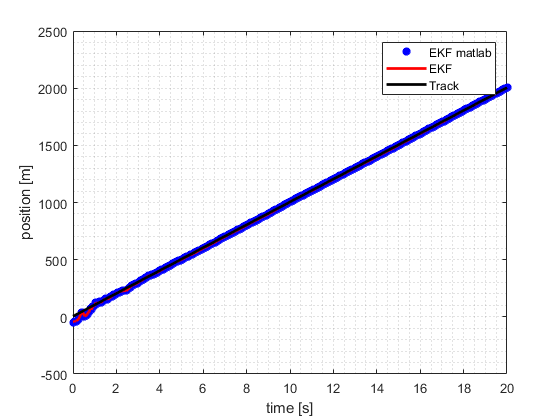

% plots

% 1 minute of measures
time = 0:dt:endtime;
set(0, 'DefaultLineLineWidth', 2)

figure
plot(time, x_posterior_mat(1,:), 'b*');
hold on; grid minor;
plot(time, x_posterior(1,:), 'r');
plot(time, xs(1,:), 'k');
xlabel('time [s]');
ylabel('position [m]')
legend( 'EKF matlab', 'EKF', 'Track');

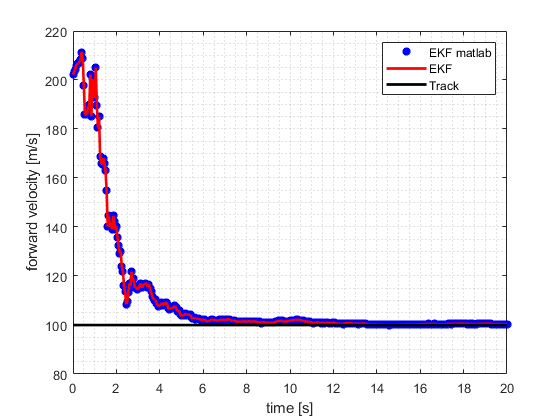

figure
plot(time, x_posterior_mat(2, :), 'b*');
hold on; grid minor;
plot(time, x_posterior(2, :), 'r');
plot(time, xs(2, :), 'k');
xlabel('time [s]');
ylabel('forward velocity [m/s]')
legend( 'EKF matlab', 'EKF', 'Track');

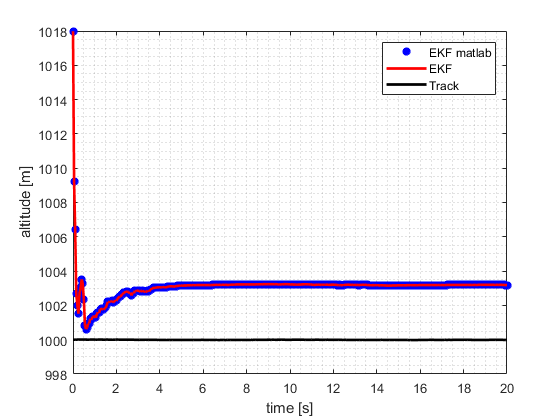


figure
plot(time, x_posterior_mat(3,:), 'b*');
hold on; grid minor;
plot(time, x_posterior(3,:), 'r');
plot(time, xs(3,:), 'k');
xlabel('time [s]');
ylabel('altitude [m]')
legend( 'EKF matlab', 'EKF', 'Track');